# ***PCA_script.mlx***

To script αυτό αναλαμβάνει τις επιθυμητές εργασίες μας σχετικά με τη μέθοδο PCA. Η ανάλυση γίνεται ξεχωριστά για περιπτώσεις μικρού και μεγάλου σφάλματος, και εξετάζει την ένταση του μεγέθους Slip και τις τιμές των γωνιών Rake.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Μέρος του κώδικα χρησιμοποιήθηκε από την εξής πηγή:
% <https://blog.cordiner.net/2010/12/02/eigenfaces-face-recognition-matlab/>

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('PCA_script.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling.mlx'
load('Workspace_ForwardModeling.mat','n_models1','n_models2','Leng','Wid')
load('MinMax.mat','Min_all','Max_all','MinVar_all')

## Προεργασίες

varianceLH = 80;  % --> Η % μεταβλητότητα των μοντέλων που επιθυμούμε να διατηρηθεί

% Εισαγωγή των μοντέλων Variable Slip (Slip και Rake)
Data_FaultL = importdata('synthetic_slipL.dat');
Slips_L(:,1) = Data_FaultL.data(:,10);
Rake_L(:,1) = Data_FaultL.data(:,13);

Data_FaultH = importdata('synthetic_slipH.dat');
Slips_H(:,1) = Data_FaultH.data(:,10);
Rake_H(:,1) = Data_FaultH.data(:,13);

for count = 1:n_models1
    Data_FaultL = importdata(['inverseL_' num2str(count) '_slip.dat']); 
    Slips_L(:,count+1) = Data_FaultL.data(:,10);
    Rake_L(:,count+1) = Data_FaultL.data(:,13);
end

for count = 1:n_models2
    Data_FaultH = importdata(['inverseH_' num2str(count) '_slip.dat']); 
    Slips_H(:,count+1) = Data_FaultH.data(:,10);
    Rake_H(:,count+1) = Data_FaultH.data(:,13);
end

% Δημιουργία πλέγματος patch του ρήγματος
Xfault = linspace(min(Data_FaultL.data(:,4)),max(Data_FaultL.data(:,4)),...
    Leng/Data_FaultL.data(1,6));
Yfault = linspace(min(Data_FaultL.data(:,5)),max(Data_FaultL.data(:,5)),...
    Wid/Data_FaultL.data(1,7))';

SizeX = size(Xfault); SizeX(1) = [];
SizeY = size(Yfault); SizeY(2) = [];

# Slip PCA

## Low Noise

Απεικονίζεται το μοντέλο Variable Slip των συνθετικών δεδομένων σε Inverse grayscale, όπου λευκό η μικρότερη και μαύρο η μεγαλύτερη τιμή slip.

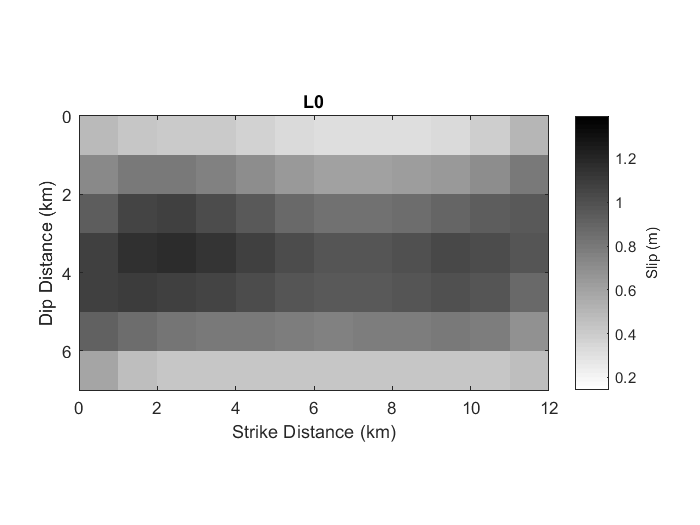

% Απεικόνιση του μοντέλου Variable Slip των συνθετικών μετρήσεων με μικρό σφάλμα
figure()

x = [min(Data_FaultL.data(:,4)) max(Data_FaultL.data(:,4))];
y = [min(Data_FaultL.data(:,5)) max(Data_FaultL.data(:,5))];

VarSlipL = reshape(Slips_L(:,1), [SizeY SizeX]);
imagesc(x,y,VarSlipL);
colormap(flipud(gray)); axis equal;
caxis([Min_all Max_all])
axis([0 Leng 0 Wid])
xticks(0:2:Leng); yticks(0:2:Wid)
h = colorbar('Ticks',0:0.2:Max_all);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
title('L0')

Εφαρμόζεται η ανάλυση PCA. Μπορεί να γίνει και αναλυτικά, αλλά εφόσον υπάρχει έτοιμη function στη Matlab θα χρησιμοποιηθεί αυτή. Μεταβλητές (variables) n θεωρούνται τα Slips του κάθε patch ενός μοντέλου, ενώ παρατηρήσεις (observations) m ο αριθμός των συγκρινόμενων μοντέλων. Καθώς στην περίπτωση μας ο αριθμός των μεταβλητών (84 patches) είναι μεγαλύτερος από των παρατηρήσεων (11 μοντέλα Variable Slip - 1 συνθετικών δεδομένων και 10 Low Noise), η PCA θα έχει m-1 βαθμούς ελευθερίας. Αυτό σημαίνει πως ο αριθμός των eigenvalues που εξάγεται θα είναι 10.

% Υπολογίζεται ο μέσος όρος slip για κάθε patch ('muL'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων slip κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsL, scoreL, evaluesL, tL, expL, muL] = pca(Slips_L');

% Τα τροποποιημένα σύνολα slip μπορούν να δειχθούν εάν αφαιρεθεί από κάθε μοντέλο...
    % Variable Slip το μοντέλο με τους μέσους όρους slip για κάθε patch ('muL').
shifted_Slips_L = Slips_L - repmat(muL',1,n_models1+1);


Μπορούμε και να δείξουμε το μοντέλο μέσων όρων Slips (Lm) σε grayscale.

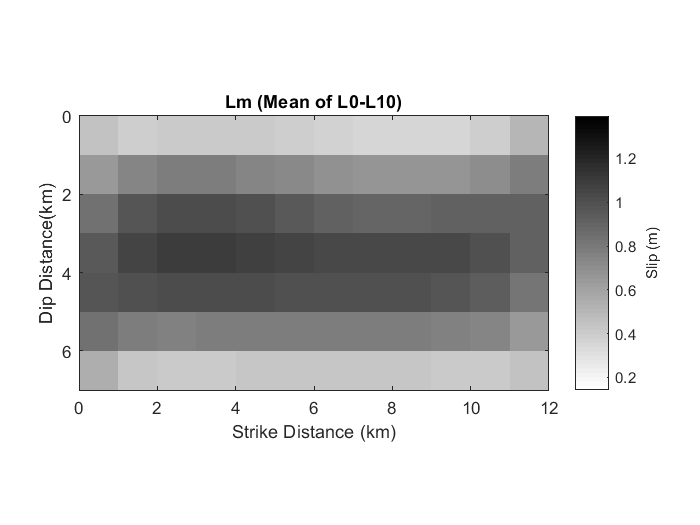

% Απεικόνιση του μοντέλου μέσων Variable Slip ('muL')
figure()

muL_res = reshape(muL', [SizeY SizeX]);
imagesc(x,y,muL_res);
colormap(flipud(gray)); axis equal;
caxis([Min_all Max_all])
xticks(0:2:Leng); yticks(0:2:Wid)
axis([0 Leng 0 Wid])
h = colorbar('Ticks',0:0.2:Max_all);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance(km)');
title('Lm (Mean of L0-L10)')

H expL δηλώνει το ποσοστό της μεταβλητότητας (variance) που εξηγεί η κάθε eigenvalue. Χρησιμοποιείται έτσι για την επιλογή του αριθμού των Principal Components, ανάλογα το ποσοστό της μεταβλητότητας που επιθυμούμε να συμπεριλάβουμε. Απεικονίζουμε τη σχέση αυτή σε ένα γράφημα Pareto.

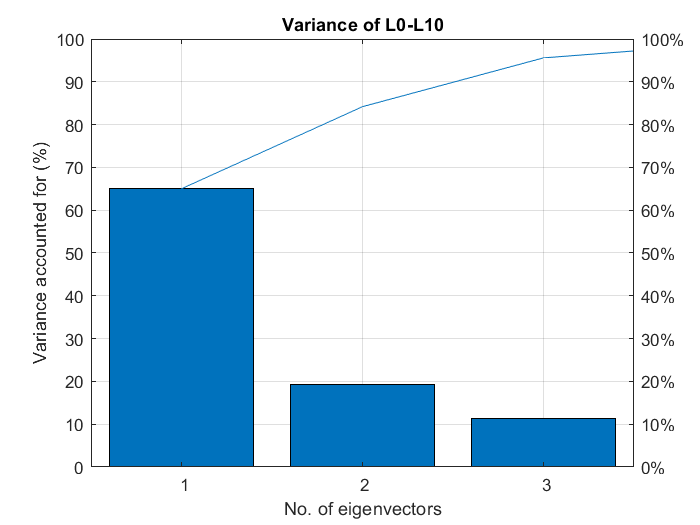

figure()
pareto(expL)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of L0-L10')

Ορίζεται ο αριθμός των Principal Components που θα χρησιμοποιήσουμε για την επιθυμητή μεταβλητότητα.

% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvL = find(cumsum(expL)>varianceLH,1);
evectorsL_pc = evectorsL(:, 1:num_eigenvL);

% Προβολή των τροποποιημένων συνόλων slip στο eigenspace με χρήση των επιλεγμένων ...
    % eigenvectors (γίνεται και αυτόματα, εκτελέστε μόνο για εναλλακτικό ...
    % Reconstruct των μοντέλων
featuresL = evectorsL_pc' * shifted_Slips_L;

Στο σημείο αυτό μπορούμε να δείξουμε το κάθε eigenvector από αυτά που επιλέξαμε. Προσοχή, δεν αναφερόμαστε ακόμα σε ανακατασκευασμένα μοντέλα Variable Slip, απλά δείχνουμε τα principal components στην επιφάνεια του ρήγματος.

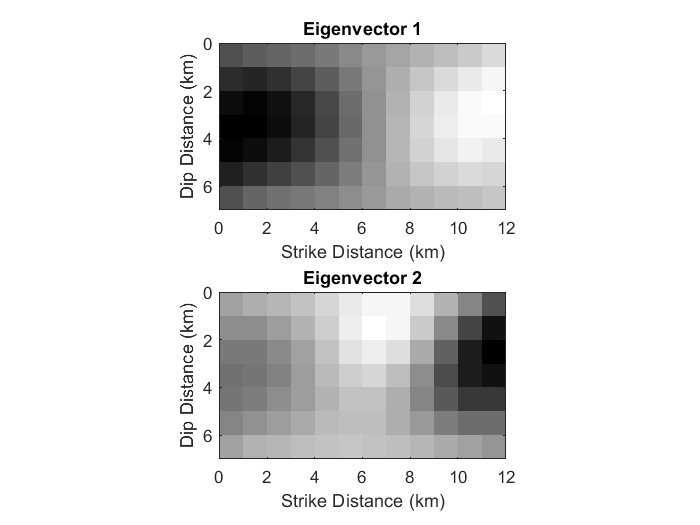

% Απεικόνιση του κάθε eigenvector που επιλέχθηκε, σε φθίνουσα σειρά
figure()
for count = 1:num_eigenvL
    
    subplot(2, ceil(num_eigenvL/2), count);
    evectorL = reshape(evectorsL(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorL);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    xticks(0:2:Leng); yticks(0:2:Wid)
    
    xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
    title(['Eigenvector ' num2str(count)])
end

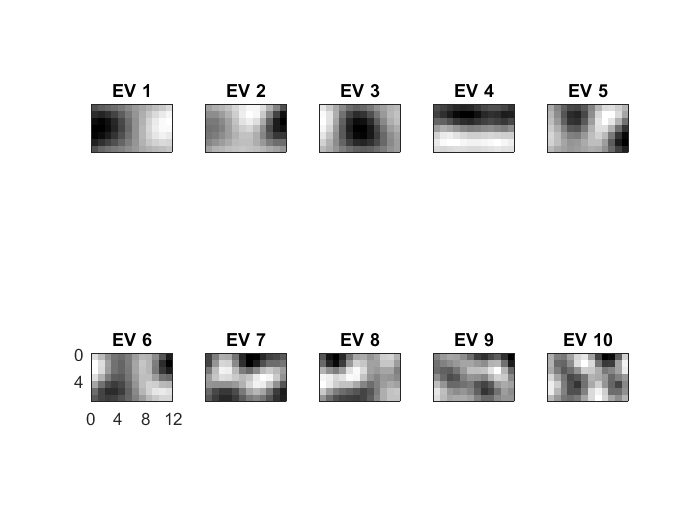

% Απεικόνιση όλων των eigenvector, σε φθίνουσα σειρά
s = size(evaluesL,1);

figure()

for count = 1:s
    
    subplot(2,ceil(s/2), count);
    evectorL = reshape(evectorsL(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorL);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(['EV ' num2str(count)])   

end

subplot(2,ceil(s/2), s/2+1);
evectorL = reshape(evectorsL(:,s/2+1), [SizeY SizeX]);
imagesc(x,y,evectorL);
colormap(flipud(gray)); axis equal;
axis([0 Leng 0 Wid])
xticks(0:4:Leng); yticks(0:4:Wid)
title(['EV ' num2str(s/2+1)])

Μπορούμε να ανακατασκευάσουμε τα μοντέλα Variable Slip που εισήγαμε στο σύστημα χρησιμοποιώντας πλέον μόνο τον αριθμό των principal components που επιλέξαμε. Τα νέα μοντέλα αποτελούν μια προσέγγιση των αρχικών ρηγμάτων, και υπάρχει ταύτιση όταν χρησιμοποιείται ο πλήρης αριθμός των eigenvectors. Στους τίτλους, το L0 αναφέρεται στο μοντέλο συνθετικών δεδομένων, ενώ τα L1, L2, L3 στα μοντέλα Low Noise 1, 2, 3 κλπ. Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε και RL0, RL1 κλπ.

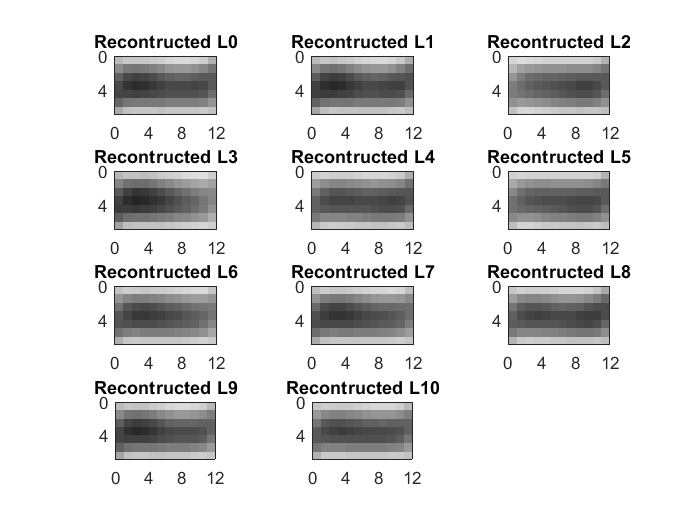

% Reconstruct των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_SlipsL = (scoreL(:,1:num_eigenvL) * evectorsL(:,1:num_eigenvL)' + ...
    repmat(muL,n_models1+1,1))';

Approx_SlipsL_alt = evectorsL_pc*featuresL+repmat(muL',1,n_models1+1); ...
    % Εναλλακτικός τρόπος

% Απεικόνιση των reconstructed Variable Slip models
figure()
for count = 1:n_models1+1
    subplot(4, ceil((n_models1+1)/4), count);
    App_SlipL = reshape(Approx_SlipsL(:,count), [SizeY SizeX]);
    imagesc(x,y,App_SlipL);
    colormap(flipud(gray)); axis equal;
    caxis([Min_all Max_all])
    axis([0 Leng 0 Wid])
    
    xticks(0:4:Leng); yticks(0:4:Wid)
    title(['Recontructed L' num2str(count-1)])
    
end

Δημιουργούμε και αρχείο στο Excel ('PCA Low Noise.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets L0, L1 κλπ. περιέχουν τα μοντέλα Variable Slip (L0: synthetic data, L1: Low Noise Model 1 etc.). Τα sheets Recontructed L0, Recontructed L1 κλπ. περιέχουν τα Reconstructed μοντέλα Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanL περιέχει το μέσο μοντέλο Variable Slip (Lm).

% Δημιουργία αρχείου 'PCA Low Noise.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_L = Data_FaultL.data(:,[1:7 11 12]);
PCL_size = size(PC_Table_L);

mkdir 'MS Files'\


filename = fullfile(pwd,'MS Files','PCA Low Noise.xlsx');
delete(filename)

T1 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Lenth (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Eigenvector (m)'};

    % Principal Components
    for count = 1:num_eigenvL
        PC_Table_L(:,10) = evectorsL(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_L,['PC' num2str(count)], ...
            ['A2:J' num2str(PCL_size(1)+1)])    
    end


T2 = T1; T2(end) = {'Slip (m)'};

    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models1+1
        PC_Table_L(:,10) = Slips_L(:,count);
        xlswrite(filename,T2,['L' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_L,['L' num2str(count-1)], ...
            ['A2:J' num2str(PCL_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models1+1
        PC_Table_L(:,10) = Approx_SlipsL(:,count);
        xlswrite(filename,T2,['Reconstructed L' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_L,['Reconstructed L' num2str(count-1)], ...
            ['A2:J' num2str(PCL_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_L(:,10) = muL';
    xlswrite(filename,T2,'MeanL','A1:J1')

    xlswrite(filename,PC_Table_L,'MeanL',['A2:J' num2str(PCL_size(1)+1)])

## High Noise

Απεικονίζεται το μοντέλο Variable Slip σε Inverse grayscale, όπου λευκό η μικρότερη και μαύρο η μεγαλύτερη τιμή slip.

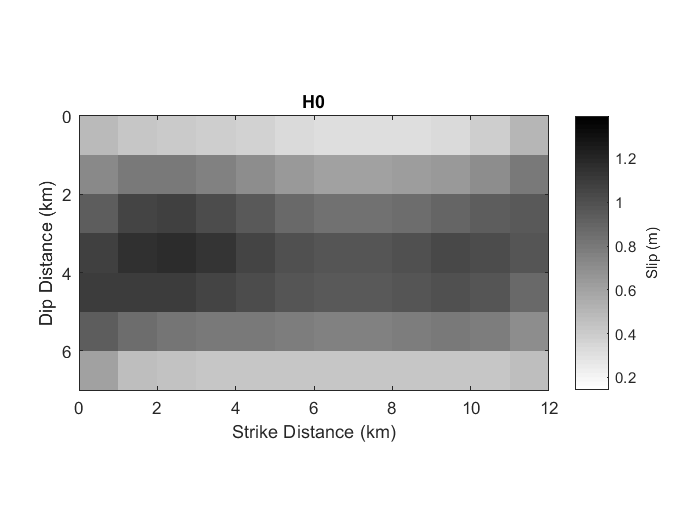

% Απεικόνιση του μοντέλου Variable Slip των συνθετικών μετρήσεων με μεγάλο σφάλμα
figure()

x = [min(Data_FaultH.data(:,4)) max(Data_FaultH.data(:,4))];
y = [min(Data_FaultH.data(:,5)) max(Data_FaultH.data(:,5))];

VarSlipH = reshape(Slips_H(:,1), [SizeY SizeX]);
imagesc(x,y,VarSlipH);
colormap(flipud(gray)); axis equal;
caxis([Min_all Max_all])
axis([0 Leng 0 Wid])
xticks(0:2:Leng); yticks(0:2:Wid)
h = colorbar('Ticks',0:0.2:Max_all);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
title('H0')

Εφαρμόζεται η ανάλυση PCA. Καθώς στην περίπτωση μας ο αριθμός των μεταβλητών (84 patches) είναι μεγαλύτερος από των παρατηρήσεων (11 μοντέλα Variable Slip - 1 συνθετικών δεδομένων και 10 High Noise), η PCA θα έχει m-1 βαθμούς ελευθερίας. Αυτό σημαίνει πως ο αριθμός των eigenvalues που εξάγεται θα είναι 10.

% Υπολογίζεται ο μέσος όρος slip για κάθε patch ('muH'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων slip κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsH, scoreH, evaluesH, tH, expH, muH] = pca(Slips_H');

% Τα τροποποιημένα σύνολα slip μπορούν να δειχθούν εάν αφαιρεθεί από κάθε μοντέλο...
    % Variable Slip το μοντέλο με τους μέσους όρους slip για κάθε patch ('muH').
shifted_Slips_H = Slips_H - repmat(muH',1,n_models2+1);


Μπορούμε και να δείξουμε το μοντέλο μέσων όρων Slips (Hm) σε grayscale.

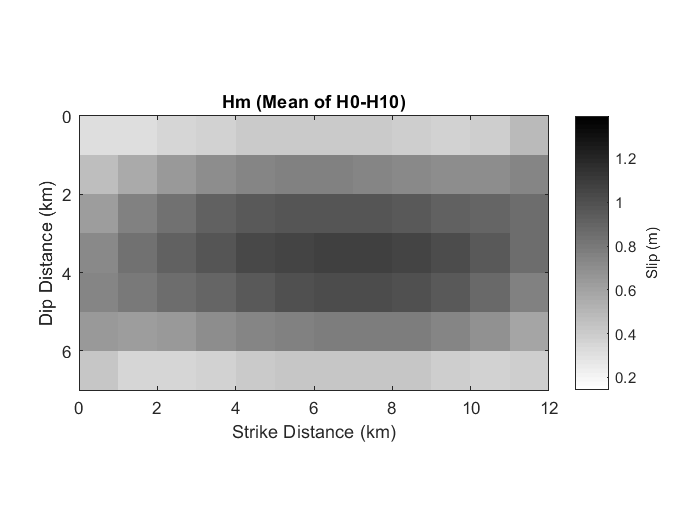

% Απεικόνιση του μοντέλου μέσων Variable Slip ('muH')
figure()

muH_res = reshape(muH', [SizeY SizeX]);
imagesc(x,y,muH_res);
colormap(flipud(gray)); axis equal;
caxis([Min_all Max_all])
xticks(0:2:Leng); yticks(0:2:Wid)
axis([0 Leng 0 Wid])
h = colorbar('Ticks',0:0.2:Max_all);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
title('Hm (Mean of H0-H10)')

H expH δηλώνει το ποσοστό της μεταβλητότητας (variance) που εξηγεί η κάθε eigenvalue. Χρησιμοποιείται έτσι για την επιλογή του αριθμού των Principal Components, ανάλογα το ποσοστό της μεταβλητότητας που επιθυμούμε να συμπεριλάβουμε. Απεικονίζουμε τη σχέση αυτή σε ένα γράφημα Pareto.

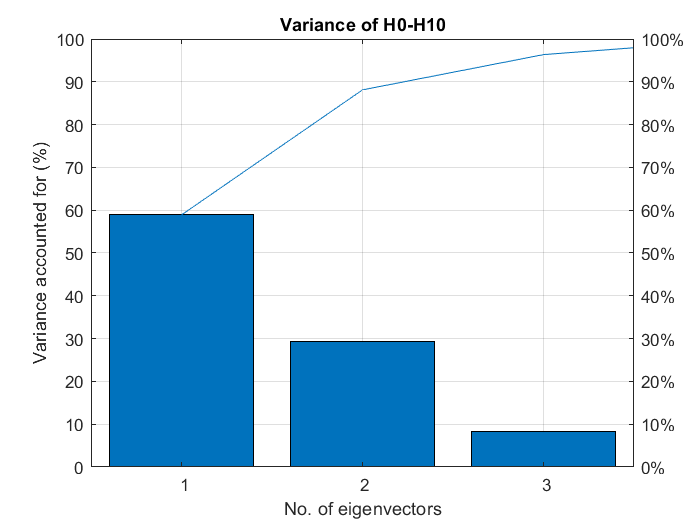

figure()
pareto(expH)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of H0-H10')

Επιλέγουμε τον αριθμό των Principal Components που θα χρησιμοποιήσουμε

% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvH = find(cumsum(expH)>varianceLH,1);
evectorsH_pc = evectorsH(:, 1:num_eigenvH);

% Προβολή των τροποποιημένων συνόλων slip στο eigenspace με χρήση των επιλεγμένων ...
    % eigenvectors (γίνεται και αυτόματα, εκτελέστε μόνο για εναλλακτικό ...
    % Reconstruct των μοντέλων
featuresH = evectorsH_pc' * shifted_Slips_H;

Στο σημείο αυτό μπορούμε να δείξουμε το κάθε eigenvector από αυτά που επιλέξαμε. Προσοχή, δεν αναφερόμαστε ακόμα σε ανακατασκευασμένα μοντέλα Variable Slip, απλά δείχνουμε τα principal components στην επιφάνεια του ρήγματος.

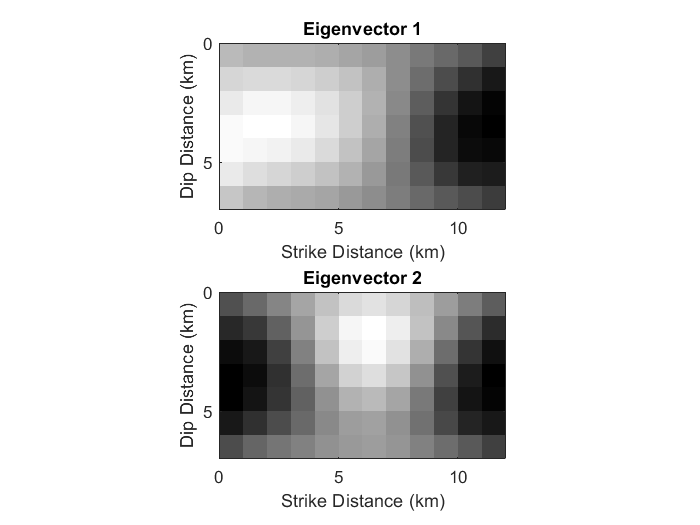

% Απεικόνιση του κάθε eigenvector που επιλέχθηκε, σε φθίνουσα σειρά
figure()
for count = 1:num_eigenvH
    
    subplot(2, ceil(num_eigenvH/2), count);
    evectorH = reshape(evectorsH(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorH);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    xticks(0:5:Leng); yticks(0:5:Wid)
    
    xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
    title(['Eigenvector ' num2str(count)])
end

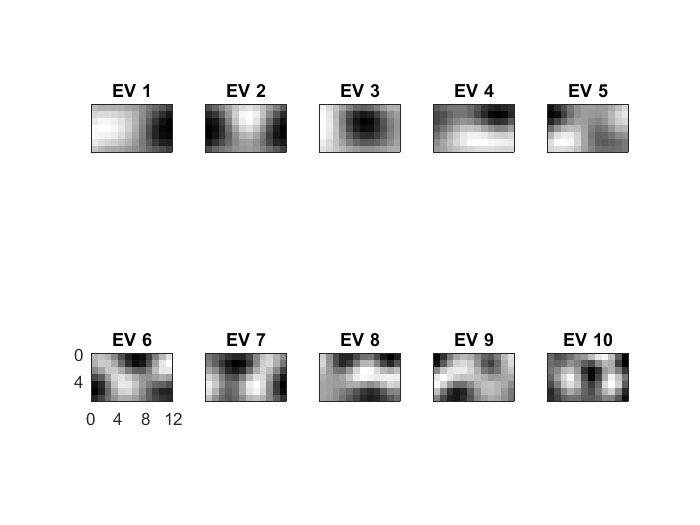

% Απεικόνιση όλων των eigenvector, σε φθίνουσα σειρά
s = size(evaluesH,1);

figure()
for count = 1:s
    
    subplot(2,ceil(s/2), count);
    evectorH = reshape(evectorsH(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorH);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(['EV ' num2str(count)])
       
end

subplot(2,ceil(s/2), s/2+1);
evectorH = reshape(evectorsH(:,s/2+1), [SizeY SizeX]);
imagesc(x,y,evectorH);
colormap(flipud(gray)); axis equal;
axis([0 Leng 0 Wid])
xticks(0:4:Leng); yticks(0:4:Wid)
title(['EV ' num2str(s/2+1)])

Μπορούμε να ανακατασκευάσουμε τα μοντέλα Variable Slip που εισάγαμε στο σύστημα χρησιμοποιώντας πλέον μόνο τον αριθμό των principal components που επιλέξαμε. Τα νέα μοντέλα αποτελούν μια προσέγγιση των αρχικών ρηγμάτων, και υπάρχει ταύτιση όταν χρησιμοποιείται ο πλήρης αριθμός των eigenvectors. Στους τίτλους, το H0 αναφέρεται στο μοντέλο συνθετικών δεδομένων, ενώ τα H1, H2, H3 στα μοντέλα High Noise 1, 2, 3 κλπ. Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε και RH0, RH1 κλπ.

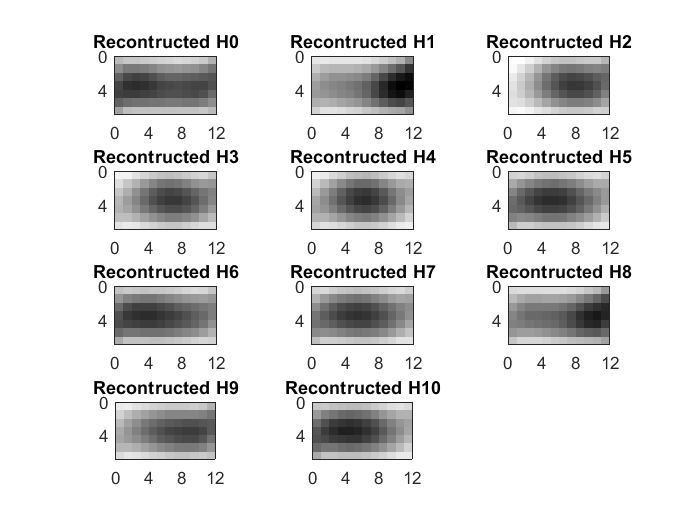

% Reconstruct των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_SlipsH = (scoreH(:,1:num_eigenvH) * evectorsH(:,1:num_eigenvH)'+ ...
    repmat(muH,n_models2+1,1))';

Approx_SlipsH_alt = evectorsH_pc*featuresH+repmat(muH',1,n_models2+1); ...
    % Εναλλακτικός τρόπος

% Απεικόνιση των reconstructed Variable Slip models
figure()
for count = 1:n_models2+1
    subplot(4, ceil((n_models2+1)/4), count);
    App_SlipH = reshape(Approx_SlipsH(:,count), [SizeY SizeX]);
    imagesc(x,y,App_SlipH);
    colormap(flipud(gray)); axis equal;
    caxis([Min_all Max_all])
    axis([0 Leng 0 Wid])
    
    xticks(0:4:Leng); yticks(0:4:Wid)
    title(['Recontructed H' num2str(count-1)])
    
end

Δημιουργούμε και αρχείο στο Excel ('PCA High Noise.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets H0, H1 κλπ. περιέχουν τα μοντέλα Variable Slip (H0: synthetic data, H1: Low Noise Model 1 etc.). Τα sheets Recontructed H0, Recontructed H1 κλπ. περιέχουν τα Reconstructed μοντέλα Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanH περιέχει το μέσο μοντέλο Variable Slip (Hm).

% Δημιουργία αρχείου 'PCA High Noise.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_H = Data_FaultH.data(:,[1:7 11 12]);
PCH_size = size(PC_Table_H);

filename = fullfile(pwd,'MS Files','PCA High Noise.xlsx');
delete(filename)

    % Principal Components
    for count = 1:num_eigenvH
        PC_Table_H(:,10) = evectorsH(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_H,['PC' num2str(count)], ...
            ['A2:J' num2str(PCH_size(1)+1)])    
    end

    
    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models2+1
        PC_Table_H(:,10) = Slips_H(:,count);
        xlswrite(filename,T2,['H' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_H,['H' num2str(count-1)], ...
            ['A2:J' num2str(PCH_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models2+1
        PC_Table_H(:,10) = Approx_SlipsH(:,count);
        xlswrite(filename,T2,['Reconstructed H' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_H,['Reconstructed H' num2str(count-1)], ...
            ['A2:J' num2str(PCH_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_H(:,10) = muH';
    xlswrite(filename,T2,'MeanH','A1:J1')

    xlswrite(filename,PC_Table_H,'MeanH',['A2:J' num2str(PCH_size(1)+1)])

## Variance - Standard Deviation (RL0-RL10 & RH0-RH10)

Στη συνέχεια θα υπολογίσουμε τη μεταβλητότητα (Variance) και τυπική απόκλιση (Standard Deviation) των Reconstructed μοντέλων RL0-RL10 και RH0-RH10.

% Υπολογισμός των Variance και Standard Deviation
VarSlip_RL = var(Approx_SlipsL,0,2);
VarSlip_RH = var(Approx_SlipsH,0,2);
SD_Slip_RL = sqrt(VarSlip_RL);
SD_Slip_RH = sqrt(VarSlip_RH);

Var_Table_RL = Data_FaultL.data(:,[1:7 11 12]);
Var_Table_RH = Data_FaultH.data(:,[1:7 11 12]);

Var_Table_RL(:,10) = VarSlip_RL;
Var_Table_RL(:,11) = SD_Slip_RL;
Var_Table_RH(:,10) = VarSlip_RH;
Var_Table_RH(:,11) = SD_Slip_RH;

VTRL_size = size(Var_Table_RL);
VTRH_size = size(Var_Table_RH);

% Εύρεση των Min και Max τιμών των Variance και Standard Deviation στο...
    % σύνολο των μοντέλων RL0-RL10, RH0-RH10, αλλά και όλων.
MinVar_RL = min(VarSlip_RL); MinSD_RL = min(SD_Slip_RL);
MaxVar_RL = max(VarSlip_RL); MaxSD_RL = max(SD_Slip_RL);

MinVar_RH = min(VarSlip_RH); MinSD_RH = min(SD_Slip_RH);
MaxVar_RH = max(VarSlip_RH); MaxSD_RH = max(SD_Slip_RH);

MinVar_R_all = min(MinVar_RL,MinVar_RH);  % Min Variance
MaxVar_R_all = max(MaxVar_RL,MaxVar_RH);  % Max Variance
MinSD_R_all = min(MinSD_RL, MinSD_RH);    % Min SD
MaxSD_R_all = max(MaxSD_RL,MaxSD_RH);     % Max SD

% Δημιουργία αρχείου 'PCA Slip Variance.xlsx' εντός του υποφακέλου 'MS Files'
T3 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Length (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Slip Variance (m^2)','Slip SD (m)'};

mkdir 'MS Files'\

filename = fullfile(pwd,'MS Files','PCA Slip Variance.xlsx');
delete(filename)

xlswrite(filename,T3,'Reconstructed Low Noise','A1:K1')

xlswrite(filename,Var_Table_RL,'Reconstructed Low Noise',['A2:K' num2str(VTRL_size(1)+1)])

xlswrite(filename,T3,'Reconstructed High Noise','A1:K1')

xlswrite(filename,Var_Table_RH,'Reconstructed High Noise',['A2:K' num2str(VTRH_size(1)+1)])

# Rake PCA

Εφαρμόζουμε την ίδια διαδικασία και για τις διευθύνσεις Rake των μοντέλων Variable Slip.

## Low Noise

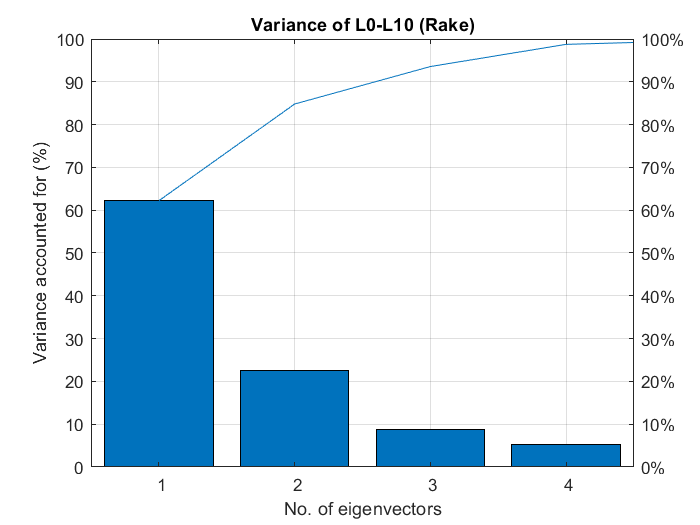

% Υπολογίζεται ο μέσος όρος rake για κάθε patch ('muRakeL'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων rake κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsRakeL, scoreRakeL, evaluesRakeL, tRakeL, expRakeL, muRakeL] = pca(Rake_L');

% Διάγραμμα Pareto
figure()
pareto(expRakeL)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of L0-L10 (Rake)')


% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvRakeL = find(cumsum(expRakeL)>varianceLH,1);
evectorsRakeL_pc = evectorsRakeL(:, 1:num_eigenvRakeL);

% Reconstruct των Rake των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_RakeL = (scoreRakeL(:,1:num_eigenvRakeL) * evectorsRakeL(:,1:num_eigenvRakeL)' + ...
    repmat(muRakeL,n_models1+1,1))';

Δημιουργούμε και αρχείο στο Excel ('PCA Low Noise Rake.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets L0, L1 κλπ. περιέχουν τα Rake των μοντέλων Variable Slip (L0: synthetic data, L1: Low Noise Model 1 etc.). Τα sheets Rake-Recontructed L0, Rake-Recontructed L1 κλπ. περιέχουν τα Rake των Reconstructed μοντέλων Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanL περιέχει τα Rake του μέσου μοντέλου Variable Slip (Lm). Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε Rake-RL0, Rake-RL1 κλπ. Αποτελούν διαφορετικές περιπτώσεις από τα μοντέλα RL0-RL10.

% Δημιουργία αρχείου 'PCA Low Noise Rake.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_RakeL = Data_FaultL.data(:,[1:7 11 12]);
PCL_Rake_size = size(PC_Table_RakeL);

mkdir 'MS Files'\


filename = fullfile(pwd,'MS Files','PCA Low Noise Rake.xlsx');
delete(filename)

    % Principal Components
    for count = 1:num_eigenvRakeL
        PC_Table_RakeL(:,10) = evectorsRakeL(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_RakeL,['PC' num2str(count)], ...
            ['A2:J' num2str(PCL_Rake_size(1)+1)])    
    end


T4 = T1; T4(end) = {'Rake (deg)'};

    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models1+1
        PC_Table_RakeL(:,10) = Rake_L(:,count);
        xlswrite(filename,T4,['L' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeL,['L' num2str(count-1)], ...
            ['A2:J' num2str(PCL_Rake_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models1+1
        PC_Table_RakeL(:,10) = Approx_RakeL(:,count);
        xlswrite(filename,T4,['Rake-Reconstructed L' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeL,['Rake-Reconstructed L' num2str(count-1)], ...
            ['A2:J' num2str(PCL_Rake_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_RakeL(:,10) = muRakeL';
    xlswrite(filename,T4,'MeanL','A1:J1')

    xlswrite(filename,PC_Table_RakeL,'MeanL',['A2:J' num2str(PCL_Rake_size(1)+1)])

## High Noise

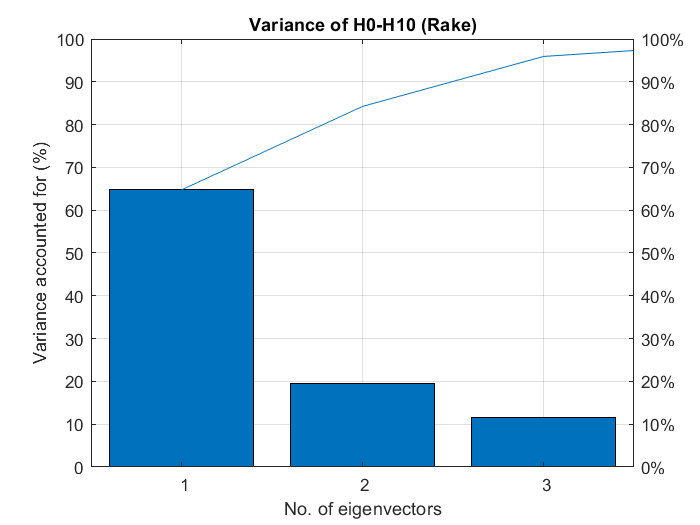

% Υπολογίζεται ο μέσος όρος rake για κάθε patch ('muRakeH'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων slip κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsRakeH, scoreRakeH, evaluesRakeH, tRakeH, expRakeH, muRakeH] = pca(Rake_H');

% Διάγραμμα Pareto
figure()
pareto(expRakeH)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of H0-H10 (Rake)')


% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvRakeH = find(cumsum(expRakeH)>varianceLH,1);
evectorsRakeH_pc = evectorsRakeH(:, 1:num_eigenvRakeH);

% Reconstruct των Rake των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_RakeH = (scoreRakeH(:,1:num_eigenvRakeH) * evectorsRakeH(:,1:num_eigenvRakeH)'+ ...
    repmat(muRakeH,n_models2+1,1))';

Δημιουργούμε και αρχείο στο Excel ('PCA High Noise Rake.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets H0, H1 κλπ. περιέχουν τα Rake των μοντέλων Variable Slip (H0: synthetic data, H1: Low Noise Model 1 etc.). Τα sheets Rake-Recontructed H0, Rake-Recontructed H1 κλπ. περιέχουν τα Rake των Reconstructed μοντέλων Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanH περιέχει τα Rake του μέσου μοντέλου Variable Slip (Hm). Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε Rake-RH0, Rake-RH1 κλπ. Αποτελούν διαφορετικές περιπτώσεις από τα μοντέλα RH0-RH10.

% Δημιουργία αρχείου 'PCA High Noise Rake.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_RakeH = Data_FaultH.data(:,[1:7 11 12]);
PCH_Rake_size = size(PC_Table_RakeH);

filename = fullfile(pwd,'MS Files','PCA High Noise Rake.xlsx');
delete(filename)

    % Principal Components
    for count = 1:num_eigenvRakeH
        PC_Table_RakeH(:,10) = evectorsRakeH(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_RakeH,['PC' num2str(count)], ...
            ['A2:J' num2str(PCH_Rake_size(1)+1)])    
    end

    
    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models2+1
        PC_Table_RakeH(:,10) = Rake_H(:,count);
        xlswrite(filename,T4,['H' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeH,['H' num2str(count-1)], ...
            ['A2:J' num2str(PCH_Rake_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models2+1
        PC_Table_RakeH(:,10) = Approx_RakeH(:,count);
        xlswrite(filename,T4,['Rake-Reconstructed H' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeH,['Rake-Reconstructed H' num2str(count-1)], ...
            ['A2:J' num2str(PCH_Rake_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_RakeH(:,10) = muRakeH';
    xlswrite(filename,T4,'MeanH','A1:J1')

    xlswrite(filename,PC_Table_RakeH,'MeanH',['A2:J' num2str(PCH_Rake_size(1)+1)])

## Rake Variance - Standard Deviation (Rake-RL0 -- Rake-RL10 & Rake-RH0 -- Rake-RH10)

Στη συνέχεια θα υπολογίσουμε τη μεταβλητότητα (Variance) και τυπική απόκλιση (Standard Deviation) των Rake των Reconstructed μοντέλων Rake-RL0 -- Rake-RL10 και Rake-RH0 -- Rake-RH10.

% Υπολογισμός των Variance και Standard Deviation
VarRake_RL = var(Approx_RakeL,0,2);
VarRake_RH = var(Approx_RakeH,0,2);
SD_Rake_RL = sqrt(VarRake_RL);
SD_Rake_RH = sqrt(VarRake_RH);

Var_Table_Rake_RL = Data_FaultL.data(:,[1:7 11 12]);
Var_Table_Rake_RH = Data_FaultH.data(:,[1:7 11 12]);

Var_Table_Rake_RL(:,10) = VarRake_RL;
Var_Table_Rake_RL(:,11) = SD_Rake_RL;
Var_Table_Rake_RH(:,10) = VarRake_RH;
Var_Table_Rake_RH(:,11) = SD_Rake_RH;

VTRL_Rake_size = size(Var_Table_Rake_RL);
VTRH_Rake_size = size(Var_Table_Rake_RH);

% Εύρεση των Min και Max τιμών των Variance και Standard Deviation στο...
    % σύνολο των μοντέλων Rake-RL0 -- Rake-RL10, Rake-RH0 -- Rake-RH10, αλλά και όλων.
MinVar_RakeRL = min(VarRake_RL); MinSD_RakeRL = min(SD_Rake_RL);
MaxVar_RakeRL = max(VarRake_RL); MaxSD_RakeRL = max(SD_Rake_RL);

MinVar_RakeRH = min(VarRake_RH); MinSD_RakeRH = min(SD_Rake_RH);
MaxVar_RakeRH = max(VarRake_RH); MaxSD_RakeRH = max(SD_Rake_RH);

MinVar_R_R_all = min(MinVar_RakeRL,MinVar_RakeRH);  % Min Variance
MaxVar_R_R_all = max(MaxVar_RakeRL,MaxVar_RakeRH);  % Max Variance
MinSD_R_R_all = min(MinSD_RakeRL, MinSD_RakeRH);    % Min SD
MaxSD_R_R_all = max(MaxSD_RakeRL,MaxSD_RakeRH);     % Max SD

% Δημιουργία αρχείου 'PCA Rake Variance.xlsx' εντός του υποφακέλου 'MS Files'
T5 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Length (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Rake Variance (deg^2)','Rake SD (deg)'};

mkdir 'MS Files'\

filename = fullfile(pwd,'MS Files','PCA Rake Variance.xlsx');
delete(filename)

xlswrite(filename,T5,'Reconstructed Low Noise','A1:K1')

xlswrite(filename,Var_Table_Rake_RL,'Reconstructed Low Noise',['A2:K' num2str(VTRL_Rake_size(1)+1)])

xlswrite(filename,T5,'Reconstructed High Noise','A1:K1')

xlswrite(filename,Var_Table_Rake_RH,'Reconstructed High Noise',['A2:K' num2str(VTRH_Rake_size(1)+1)])

% Αποθήκευση του Workspace
save PCA.mat